## Lectura de archivo con información

Y = readmatrix('datosRGB_papa_inf.txt');
% La frecuencia de muestreo, numero de frames y duracion del video son
% extraidos a mano de los atributos del objeto v de la primera parte del
% archivo
fs = 30.0144; % frecuencia de muestreo
n = 945; % number of frames
D = 31.5051; %Duracion del video
f = [0:n-1]*fs/n;
t = linspace(0,D,n);

% Filtrado de la señal
Yfilt = bandpass(Y,[0.8,140/60],fs);

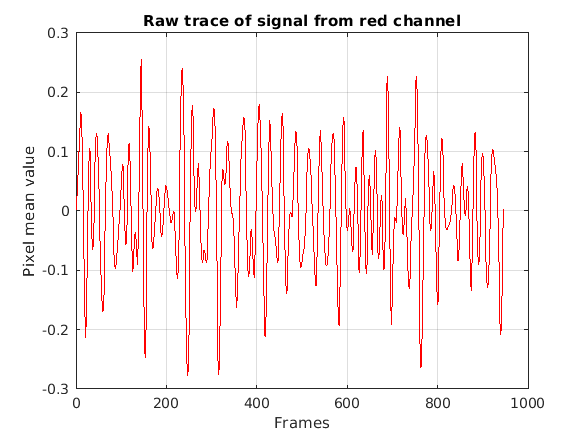

% Graficas de la señal
%subplot(3,1,1)
plot(1:n,Yfilt(:,1),'r');
xlabel("Frames")
ylabel("Pixel mean value")
grid on
title("Raw trace of signal from red channel")

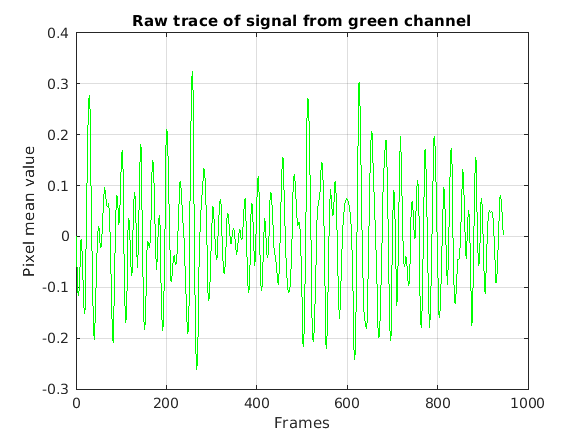


%subplot(3,1,2)
plot(1:n,Yfilt(:,2),'g');
xlabel("Frames")
ylabel("Pixel mean value")
grid on
title("Raw trace of signal from green channel")

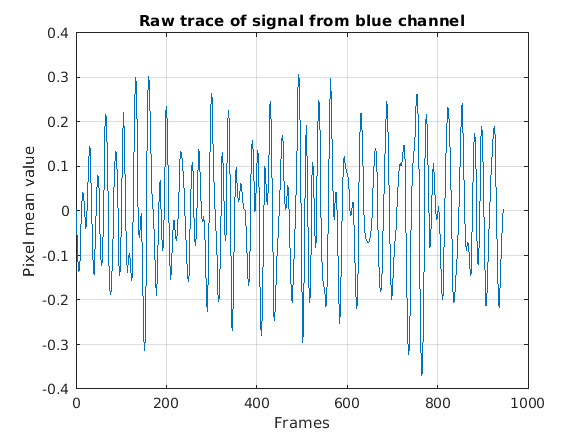


%subplot(3,1,3)
plot(1:n,Yfilt(:,3));
xlabel("Frames")
ylabel("Pixel mean value")
grid on
title("Raw trace of signal from blue channel")
hold off

## Aplicación de la FFT para ver frecuencias

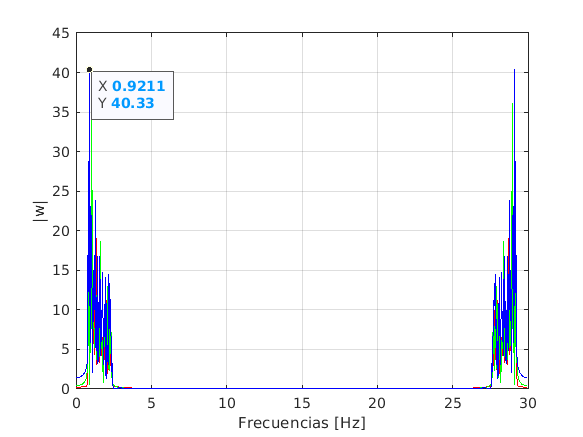

Yjw = fft(Yfilt);
plot(f,abs(Yjw(:,1)),'r')
grid on;
xlabel("Frecuencias [Hz]")
ylabel("|w|")

hold on
plot(f,abs(Yjw(:,2)),'g')
grid on;
xlabel("Frecuencias [Hz]")
ylabel("|w|")

hold on
plot(f,abs(Yjw(:,3)),'b')
grid on;
xlabel("Frecuencias [Hz]")
ylabel("|w|")

## ICA para la señal filtrada

q = 3;
Mdl = rica(Yfilt,q,"NonGaussianityIndicator",ones(q,1),"Standardize",true); % descomposicion de la señal en señales fuente
S = transform(Mdl,Yfilt);

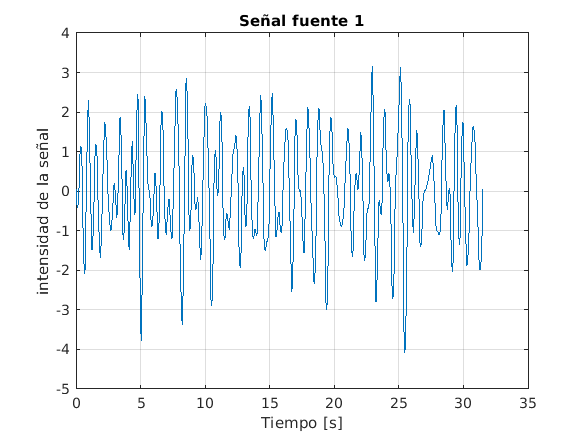

% grafica de las señales fuente
figure
plot(t,S(:,1));
grid on;
xlabel('Tiempo [s]')
ylabel('intensidad de la señal')
title("Señal fuente 1")

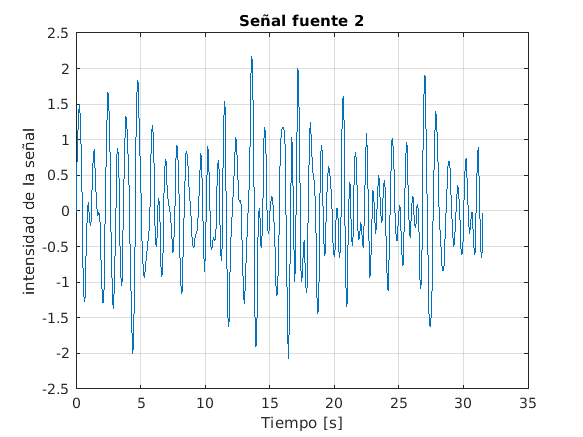


figure
plot(t,S(:,2));
grid on;
xlabel('Tiempo [s]')
ylabel('intensidad de la señal')
title("Señal fuente 2")

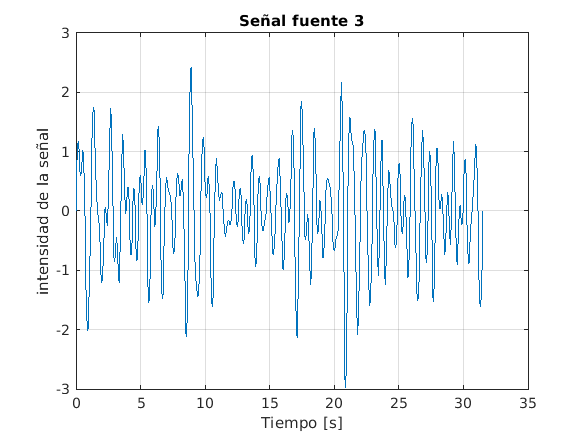



figure
plot(t,S(:,3));
grid on;
xlabel('Tiempo [s]')
ylabel('intensidad de la señal')
title("Señal fuente 3")

## Calculo de la PSD para cada señal fuente

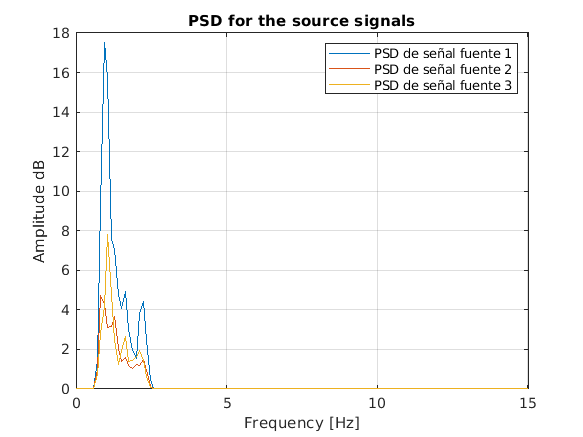

[Pxx,F] = pwelch(S(:,1),[],[],[],fs,'psd');
Pxx = Pxx*2*pi; % converting to normal PSD and not power per rad per sample
figure, plot(F,Pxx)
xlabel('Frequency [Hz]')
ylabel('Amplitude dB')
grid on
xlim([0 max(F)])
hold on



[Pxx2,F2] = pwelch(S(:,2),[],[],[],fs,'psd');
Pxx2 = Pxx2*2*pi; % converting to normal PSD and not power per rad per sample
plot(F2,Pxx2)
xlabel('Frequency [Hz]')
ylabel('Amplitude dB')
grid on
xlim([0 max(F2)])
hold on



[Pxx3,F3] = pwelch(S(:,3),[],[],[],fs,'psd');
Pxx3 = Pxx3*2*pi; % converting to normal PSD and not power per rad per sample
plot(F3,Pxx3)
xlabel('Frequency [Hz]')
ylabel('Amplitude dB')
grid on
xlim([0 max(F3)])
title('PSD for the source signals')

legend("PSD de señal fuente 1","PSD de señal fuente 2","PSD de señal fuente 3")


i1 = find(Pxx ==max(Pxx));
disp("Frecuencia con Densidad espectral maxima en señal fuente 1:")

Frecuencia con Densidad espectral maxima en señal fuente 1:


F(i1)

ans = 0.9380


i2 = find(Pxx2 ==max(Pxx2));
disp("Frecuencia con Densidad espectral maxima en señal fuente 2:")

Frecuencia con Densidad espectral maxima en señal fuente 2:


F(i2)

ans = 0.8207


i3 = find(Pxx3 ==max(Pxx3));
disp("Frecuencia con Densidad espectral maxima en señal fuente 3:")

Frecuencia con Densidad espectral maxima en señal fuente 3:


F(i3)

ans = 1.0552